% rgb
map=([1 1 0; 1 0 0; 0 1 1; 0.2 0.2 0.2; 1 0 1; 0.8 0.8 0.8])

map =     1.0000    1.0000         0
    1.0000         0         0
         0    1.0000    1.0000
    0.2000    0.2000    0.2000
    1.0000         0    1.0000
    0.8000    0.8000    0.8000


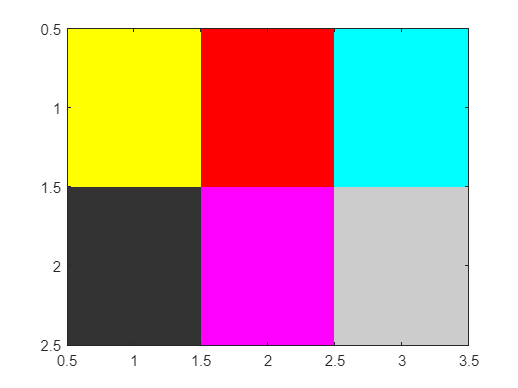

image([1 , 2 , 3; 4, 5, 6])
colormap(map)

N=[1 2 3; 4 5 6; 7 8 9; 10 11 12; 13 14 15]

N =      1     2     3
     4     5     6
     7     8     9
    10    11    12
    13    14    15


N(1:3:end, 1)

ans =      1
    10


N(1:3:end, :)

ans =      1     2     3
    10    11    12


v1=[1, 1, 1, 1]

v1 =      1     1     1     1


v2=[0.5, 0.25, 0, 0.25];
v3=[0.25, 0.5, 0, 0.5, 1]

v3 =     0.2500    0.5000         0    0.5000    1.0000


v1 .* v2

ans =     0.5000    0.2500         0    0.2500


s1=sum(v1 .* v2)

s1 = 1

%v1 .* v3
%s2=sum(v1 .* v3);

m6=[1 2 3; 4 5 6; 7 8 9];
m7=[-2 3 1; 0 2 -7; 1 3 6];

u1= m6>3

u1 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u2= (m6 > 3 & m7==-7)

u2 = 3×3 logical array
   0   0   0
   0   0   1
   0   0   0


u3= (m6 > 3 | m7==-7)

u3 = 3×3 logical array
   0   0   0
   1   1   1
   1   1   1


u4= ( (m6+m7) >= 4 & m6>5)

u4 = 3×3 logical array
   0   0   0
   0   0   0
   1   1   1


bild = imread('Butterfly.tif');
fargbild = double(bild) / 255;
mygray = (fargbild(:,:,1) + fargbild(:,:,2) + fargbild(:,:,3))/3

mygray =     0.1817    0.2052    0.1817    0.2092    0.2405    0.2288    0.2288    0.2092    0.2105    0.1948    0.1974    0.2052    0.2000    0.1908    0.1948    0.2157    0.1974    0.2170    0.2327    0.2353    0.2497    0.2680    0.2719    0.2588    0.2654    0.2575    0.2497    0.2497    0.2497    0.2497    0.2418    0.2379    0.2157    0.2431    0.2549    0.2431    0.2353    0.2431    0.2431    0.2392    0.2092    0.2092    0.2170    0.2196    0.2118    0.2131    0.2209    0.2248    0.2105    0.2078
    0.2209    0.2405    0.2131    0.2209    0.2405    0.2248    0.2288    0.2209    0.2065    0.2065    0.2131    0.2131    0.2039    0.1948    0.1987    0.2078    0.2039    0.2248    0.2405    0.2444    0.2497    0.2614    0.2601    0.2510    0.2536    0.2536    0.2497    0.2497    0.2536    0.2497    0.2418    0.2340    0.2588    0.2588    0.2510    0.2392    0.2314    0.2314    0.2235    0.2118    0.2327    0.2327    0.2288    0.2235    0.2118    0.2052    0.2052    0.2013    0.2026

imwrite(mygray, 'mygray.png')